# **Fig 3**

## **Net city-wide demand**

clear; clc; close all;


T_right  = readtable("../data/SystemLoad/SystemLoad_DistrictOpt_v1_2025-10-20.csv");  % District-level
T_left = readtable("../data/SystemLoad/SystemLoad_SystemOpt_v1_2025-10-20.csv");    % System-level


set(groot,'defaultAxesFontName','Helvetica');
set(groot,'defaultTextFontName','Helvetica');

fig_w_cm = 18.3;   % two-column width
fig_h_cm = 9.6;    % compact height; shared legend at bottom
figure('Units','centimeters','Position',[2 2 fig_w_cm fig_h_cm]);
tl = tiledlayout(1,2,'Padding','compact','TileSpacing','compact');

base_pt  = 7.5;  label_pt = 8.5;  line_w = 1.8;
gridCol  = 0.85*[1 1 1];


C = struct();
C.deepRed      = [0.70 0.15 0.15];
C.lightRed     = [0.85 0.45 0.45];
C.blue         = [0.20 0.50 0.80];
C.lightBlue    = [0.45 0.70 0.90];
C.blueGray = [0.25 0.25 0.25];     % benchmark dark neutral gray


plot_vars = {'SystemLoad','OnlyV2G','NetLoad','V2G','Uncontrolled'};
labels    = {'No PV, no EV','Only V2G','PV only','PV + V2G','PV + uncontrolled charging'};

curveColors = containers.Map( plot_vars, ...
   {C.blueGray, C.lightRed, C.blue, C.deepRed, C.lightBlue} );


curveStyles = containers.Map( ...
    plot_vars, ...
    {':', '--', '-', '-', "-."} ...
);


all_left  = T_left{:, plot_vars};
all_right = T_right{:, plot_vars};
ymin_all  = floor(min([all_left(:); all_right(:)]) / 100)*100;
ymax_all  = ceil( max([all_left(:); all_right(:)]) / 100)*100;

% -------- Left panel: System-level --------
ax1 = nexttile; hold(ax1,'on');
hLines = gobjects(1, numel(plot_vars));
for i = 1:numel(plot_vars)
    v = plot_vars{i};
    hLines(i) = plot(ax1, T_left.Time, T_left.(v), ...
        'LineStyle', curveStyles(v), 'Color', curveColors(v), 'LineWidth', line_w, ...
        'DisplayName', labels{i});

end

%disp("Peak recttion: " + max(T_left.(v)) );

Peak recttion: 12167.1968


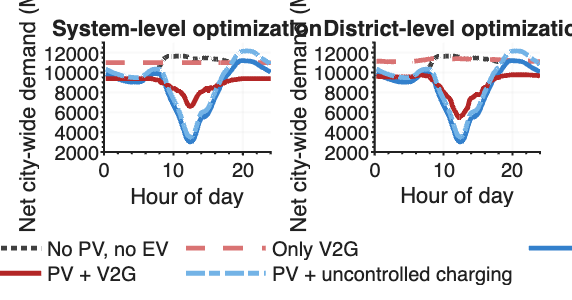

title(ax1, 'System-level optimization', 'FontSize', base_pt);
xlabel(ax1, 'Hour of day', 'FontSize', label_pt);
ylabel(ax1, 'Net city-wide demand (MW)', 'FontSize', label_pt);
xlim(ax1, [0 24]); ylim(ax1, [2000 13000]);
grid(ax1,'on'); ax1.GridColor = gridCol;
set(ax1,'FontSize',base_pt,'TickDir','out','LineWidth',0.8, ...
    'Box','off','XMinorTick','on','YMinorTick','on','TickLength',[0.015 0.01]);

% -------- Right panel: District-level --------
ax2 = nexttile; hold(ax2,'on');
for i = 1:numel(plot_vars)
    v = plot_vars{i};
    plot(ax2, T_right.Time, T_right.(v), ...
        'LineStyle', curveStyles(v), 'Color', curveColors(v), 'LineWidth', line_w, ...
        'DisplayName', labels{i});

end

title(ax2, 'District-level optimization', 'FontSize', base_pt);
xlabel(ax2, 'Hour of day', 'FontSize', label_pt);
ylabel(ax2, 'Net city-wide demand (MW)', 'FontSize', label_pt);
xlim(ax2, [0 24]); ylim(ax2, [2000 13000]);
grid(ax2,'on'); ax2.GridColor = gridCol;
set(ax2,'FontSize',base_pt,'TickDir','out','LineWidth',0.8, ...
    'Box','off','XMinorTick','on','YMinorTick','on','TickLength',[0.015 0.01]);


lg = legend(hLines, labels, 'Orientation','horizontal', 'NumColumns', 3, 'Box','off');
lg.Layout.Tile = 'south';
lg.FontSize = base_pt;

%{ %}
% Export vector PDF
outdir = '../results'; if ~exist(outdir,'dir'), mkdir(outdir); end
exportgraphics(gcf, fullfile(outdir,"SystemLoad_SystemOpti_LocalOpti_v5_" +...
    string(datetime("now", "Format", "yyyy-MM-dd")) + ".pdf"), ...
    'ContentType','vector','BackgroundColor','none');